# Through this example you will learn how to use MathWorks tools for various steps of a nonlinear MPC workflow with neural state-space prediction model

## Nonlinear MPC with Neural State-Space Prediction Model Control Design Workflow

# 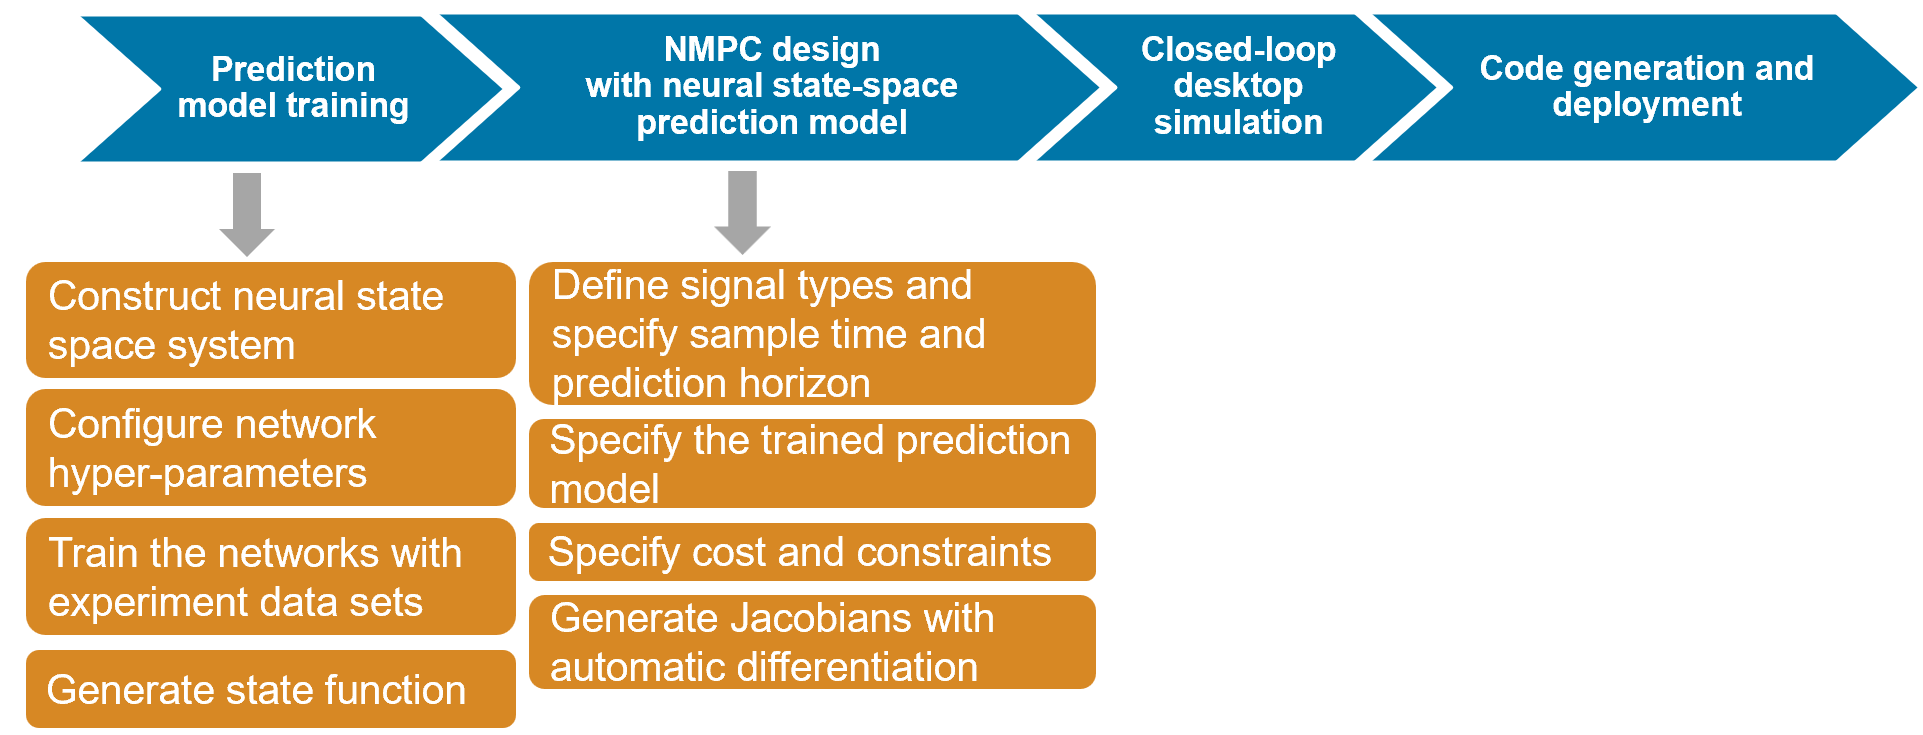

**Plant:** You will be using a simulation model of a house heating system as your plant.

**Goal:** Control the heating input of a house to achieve the following objectives:

- Maintain the house temperature within [$20\degree$C, $22\degree$C]

- Minimize energy cost

## **House Heating System**

The plant for this example is a house heating system. The model is implemented using Simulink Simscape blocks, contains a heater and a house structure with four parts: inside air, house walls, windows, and roof. The house exchanges heat with the environment through its walls, windows, and roof. Each path is simulated as a combination of a thermal convection, thermal conduction, and the thermal mass. The simulation calculates the indoor house temperature. It has:

- One manipulated variable: Heater input which can vary from 0 to 1

- One measured disturbance: Outdoor temperature in $\degree$C

- One measured output: House temperature in $\degree$C

## Control Objectives

A nonlinear MPC controller uses heater to control house temperature with the following objectives:

- Maintain the house temperature within [$20\degree$C, $22\degree$C]

- Minimize energy cost 

In this example, electricity pricing fluctuates during 24 hours. As the "Time of use electricty pricing" shown below, the heating cost is most expensive between 10am and 9pm, which we know in advance. Therefore we can utilize MPC's preview capability to minimize the electricity cost by keeping the house temperature close to the lower boundary of $20\degree$C during on-peak hours.

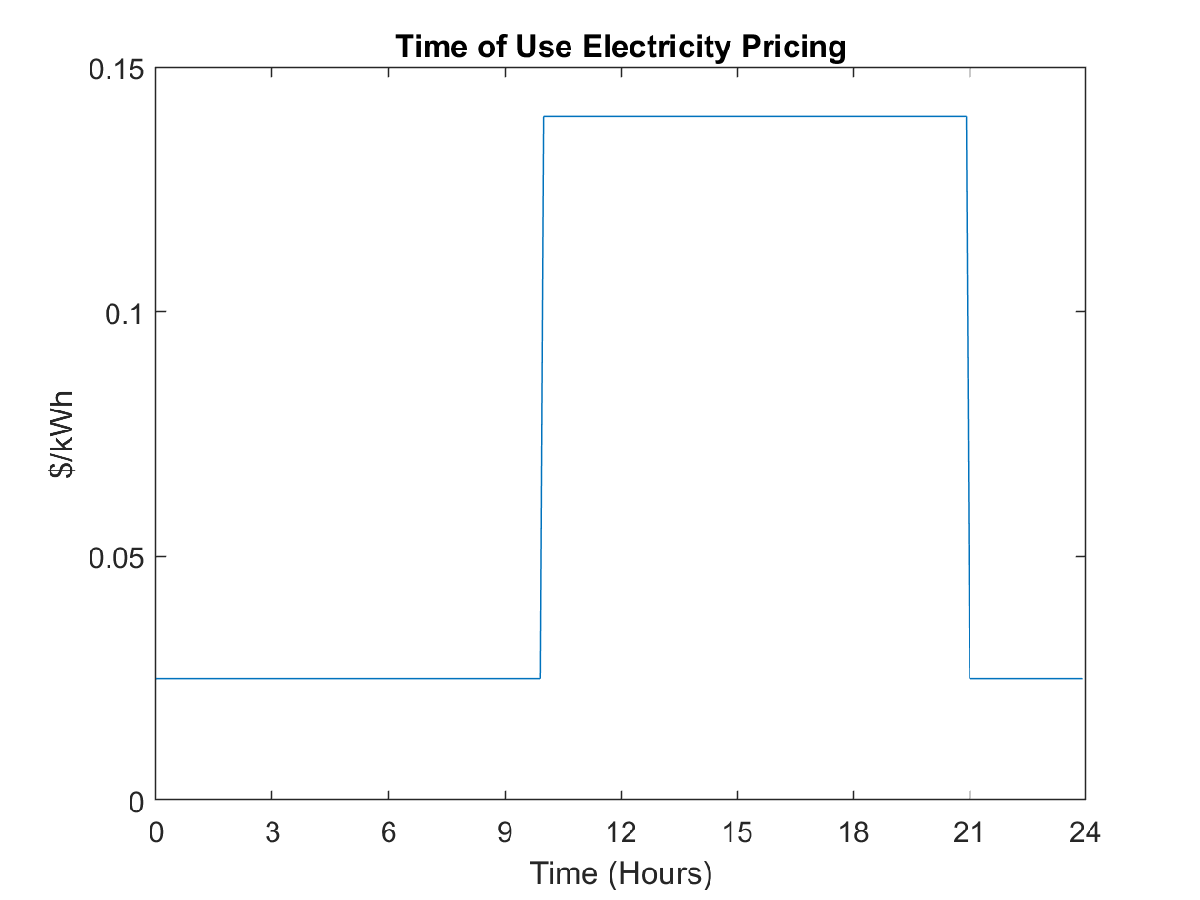

## **Nonlinear MPC Using Neural State-Space Prediction Model**

MPC requires a model to predict plant behavior in the future, and based on the model, it formulates and solves a constrained optimization problem at each control interval. In this example, we assume we don't have enough domain knowledge to manually derive a proper low-order, medium-fidelity, first-principle house model that is suitable for MPC to use. Therefore we must rely on data-driven approaches to identify a dynamic model. Among several nonlinear modeling techniques available from System Identification Toolbox, we choose to identify a neural state space model. The MPC control structure is illustrated below.

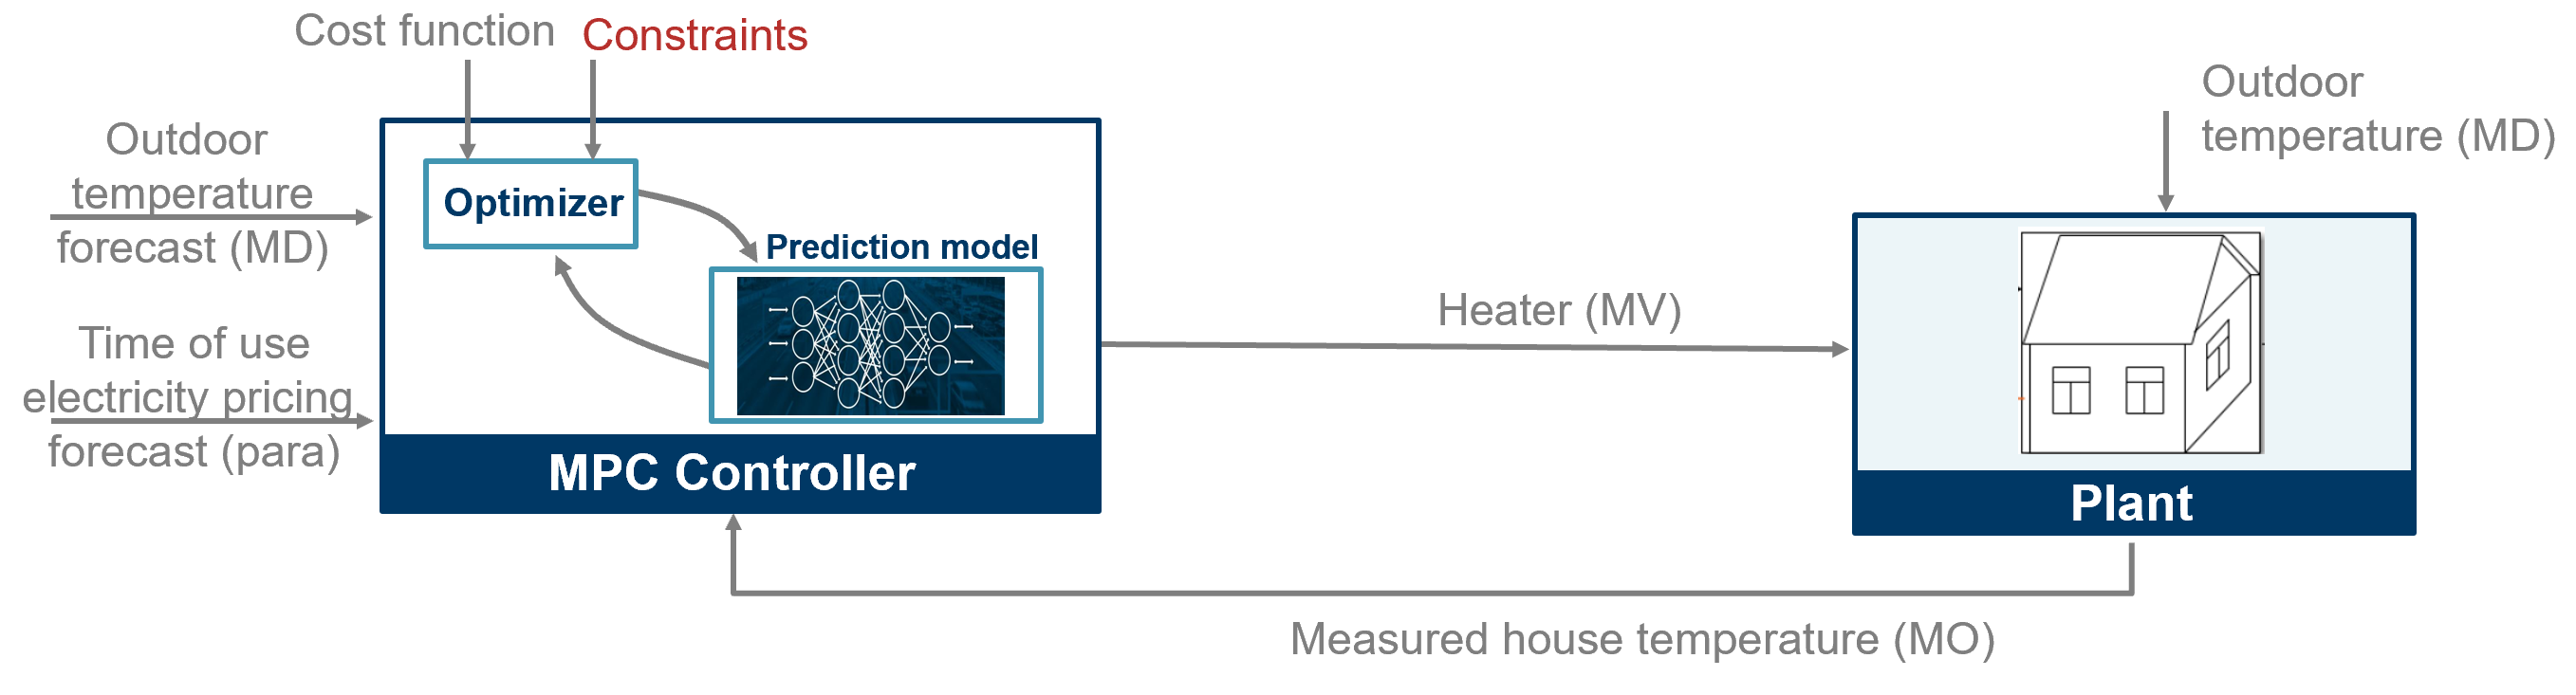

The Simulink model was already created for you. Please note the following:

- "Multistage Nonlinear MPC" block from the Model Predictive Control Toolbox is used in the model. More details regarding this block can be found in this [link](https://www.mathworks.com/help/mpc/ref/multistagenonlinearmpccontroller.html).

- If you double click the "Multistage Nonlinear MPC" block, you can see that the nl`obj `which you will be defining below is specified as a parameter.

- Forecast of outdoor temperature is provided as a measure disturbance.

- Forecast of time of use electricity use pricing is provided as a stage parameter.

clear;
cd(fileparts(which('HouseHeatingSystem_MPC.mlx'))); % changing current folder

open_system('house_heating_system');

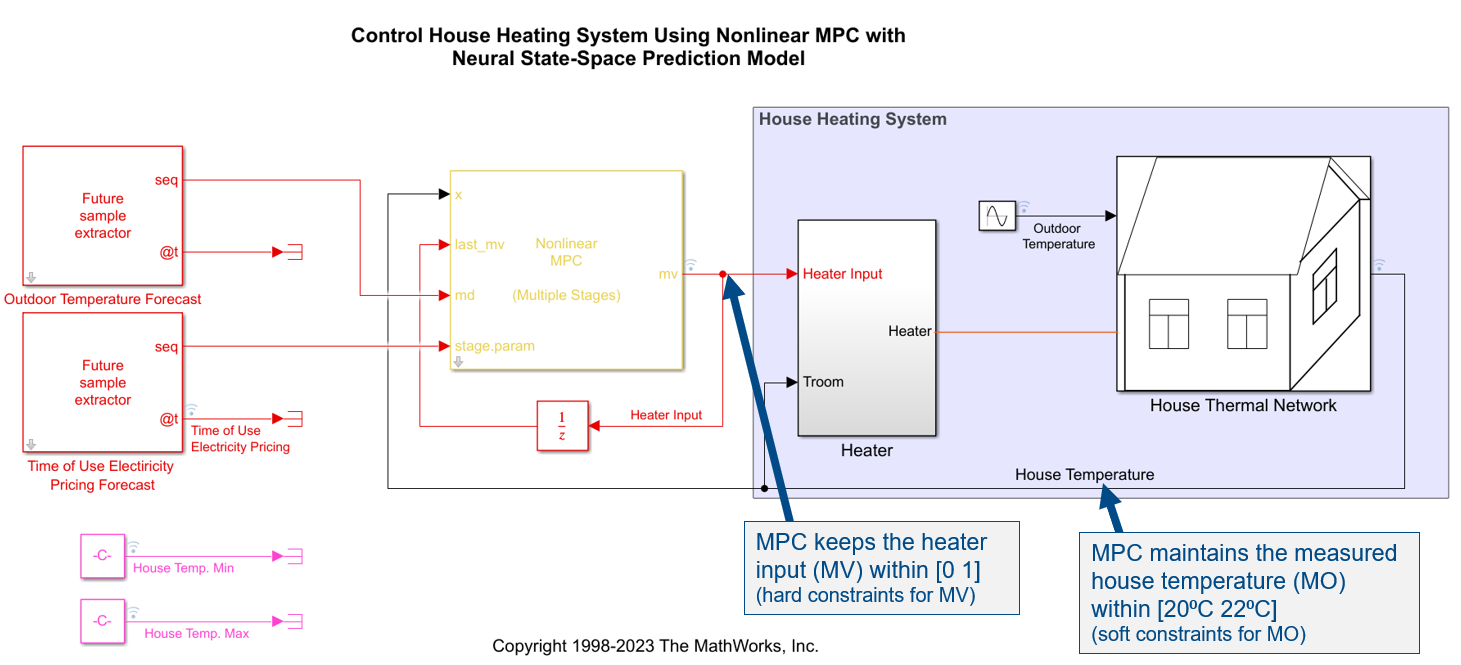

## Training Neural State-Space Prediction Model

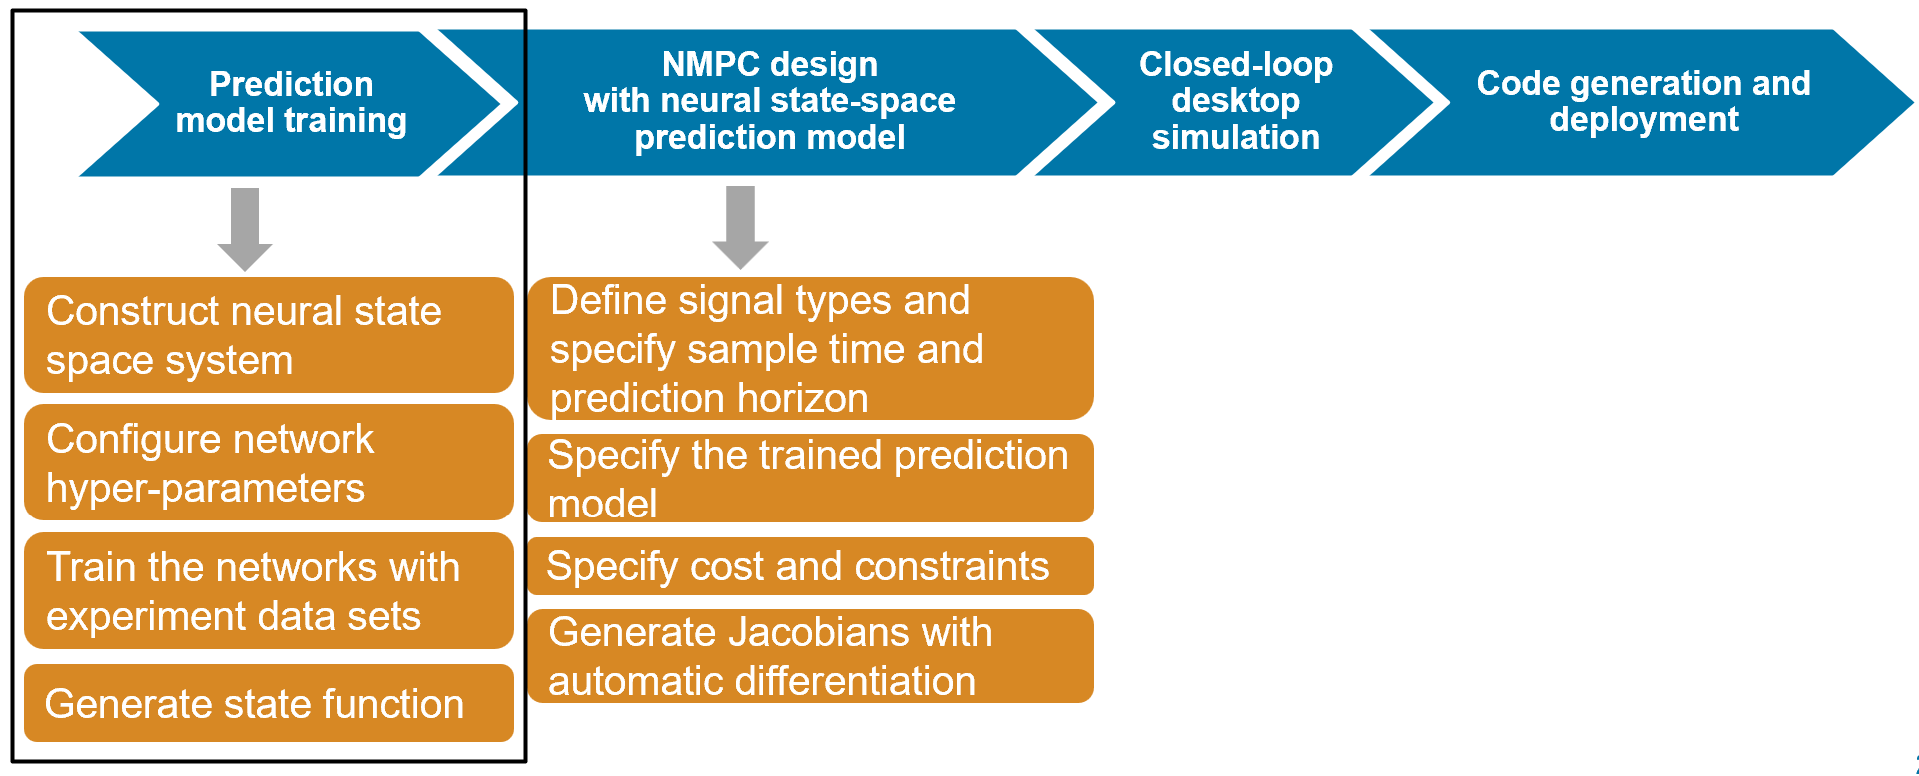

### Load training and validation data

We have already created training and validation data sets for you and is saved in the "training_data.mat" file. You will be using this for training the neural state-space model.

addpath('./data/');
addpath('./helperFunctions/');
addpath('./functions/');
% Fix the random generator seed for reproducible training result.
rng(0);
% Change this to true if you want to do the training. If not, a pretrained
% model will be loaded.
do_training = false;
% Loading the presaved training and validation data
load('training_data.mat');

Visualizing one of the training data set.

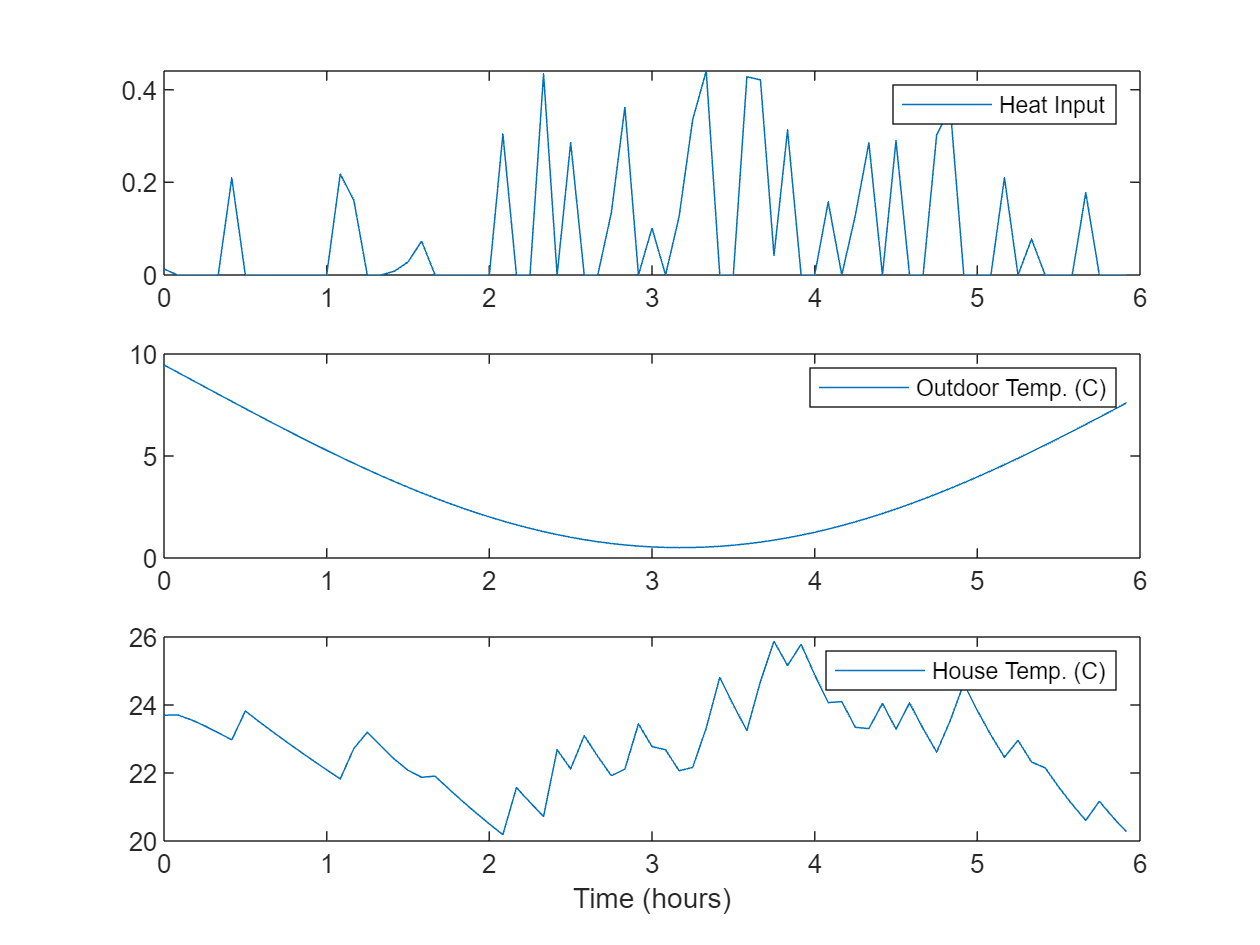

figure;
subplot(3,1,1);
plot(hours(U{1,1}.Time),U{1,1}.heatInput);
legend('Heat Input');
subplot(3,1,2);
plot(hours(U{1,1}.Time),U{1,1}.envTemp);
legend('Outdoor Temp. (C)');
subplot(3,1,3);
plot(hours(X{1,1}.Time),X{1,1}.houseTemp);
legend('House Temp. (C)');
xlabel('Time (hours)');

Create a discrete-time neural state-space model and configure its state network parameters. 

Use [`idNeuralStateSpace`](https://www.mathworks.com/help/ident/ref/idneuralstatespace.idneuralstatespace.html) to create a discrete-time neural state-space object with one state and two inputs. By default, the state network has two hidden layers each with 64 neurons and an hyperbolic tangent activation function. Use [`createMLPNetwork`](https://www.mathworks.com/help/ident/ref/idneuralstatespace.idneuralstatespace.createmlpnetwork.html) and dot notation, to re-configure the state network. Specify two hidden layers of 32 neurons each.

if do_training
    % Define a discrete-time neural state-space model with 1 state and 2 inputs and
    % sample time of 300 seconds
    obj = idNeuralStateSpace(1,NumInputs=2, Ts=Ts);
    
    % Configure the state network to have two hidden layers each with 32
    % nodes
    obj.StateNetwork = createMLPNetwork(obj,'state', LayerSizes=[32 32]);
    
    % Create training options object for state network
    options = nssTrainingOptions('adam');
    % Specify the maximum number of epochs for training to terminate
    options.MaxEpochs = 300;
    % Divide the data sets into 4 mini-batches, each having 999 data
    % points
    options.MiniBatchSize = N;
    % Specify learning rate
    options.LearnRate = 0.002;
    
    % Train the state network
    nss = nlssest(U,X,obj,options,'UseLastExperimentForValidation',true);
else
    % Load a pretrained neural state-space model
    load('trained_nss_obj.mat'); 
end

### 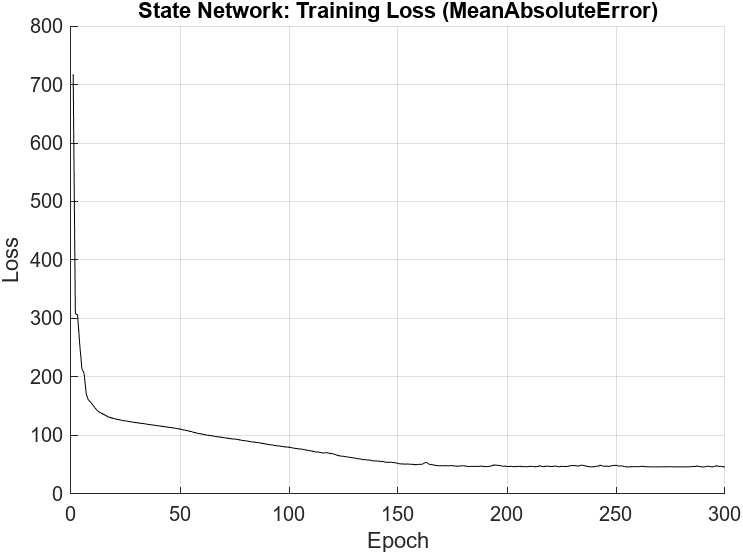

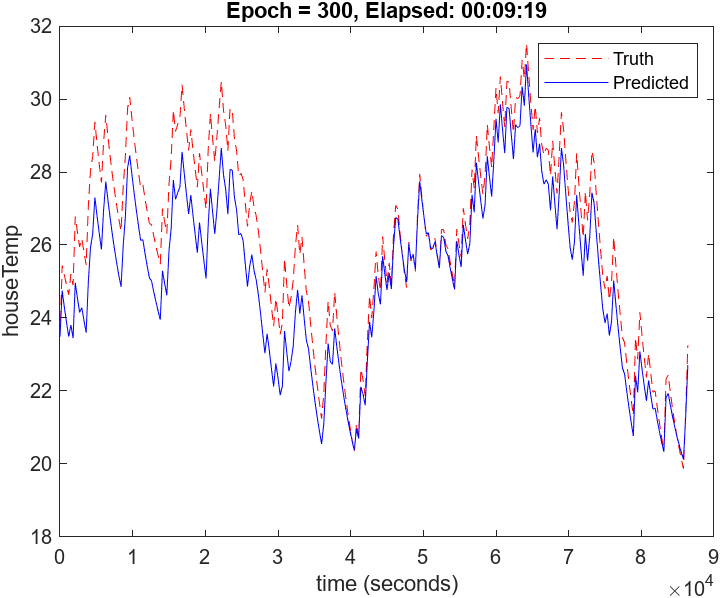

### Generate state MATLAB function for nonlinear MPC

Generate MATLAB function that evaluates the state function of the neural state-space object. We will use the [generateMATLABFunction](https://www.mathworks.com/help/ident/ref/idneuralstatespace.idneuralstatespace.generatematlabfunction.html) which generates evaluation functions for the state and Jacobians of a neural state-space object. Note that we won't be using this Jacobian function for MPC instead we will use the one generated from the MPC object in the next section.

generateMATLABFunction(nss,'stateFcn');

## Design Multistage Nonlinear MPC with Neural State-Space Prediction Model

##  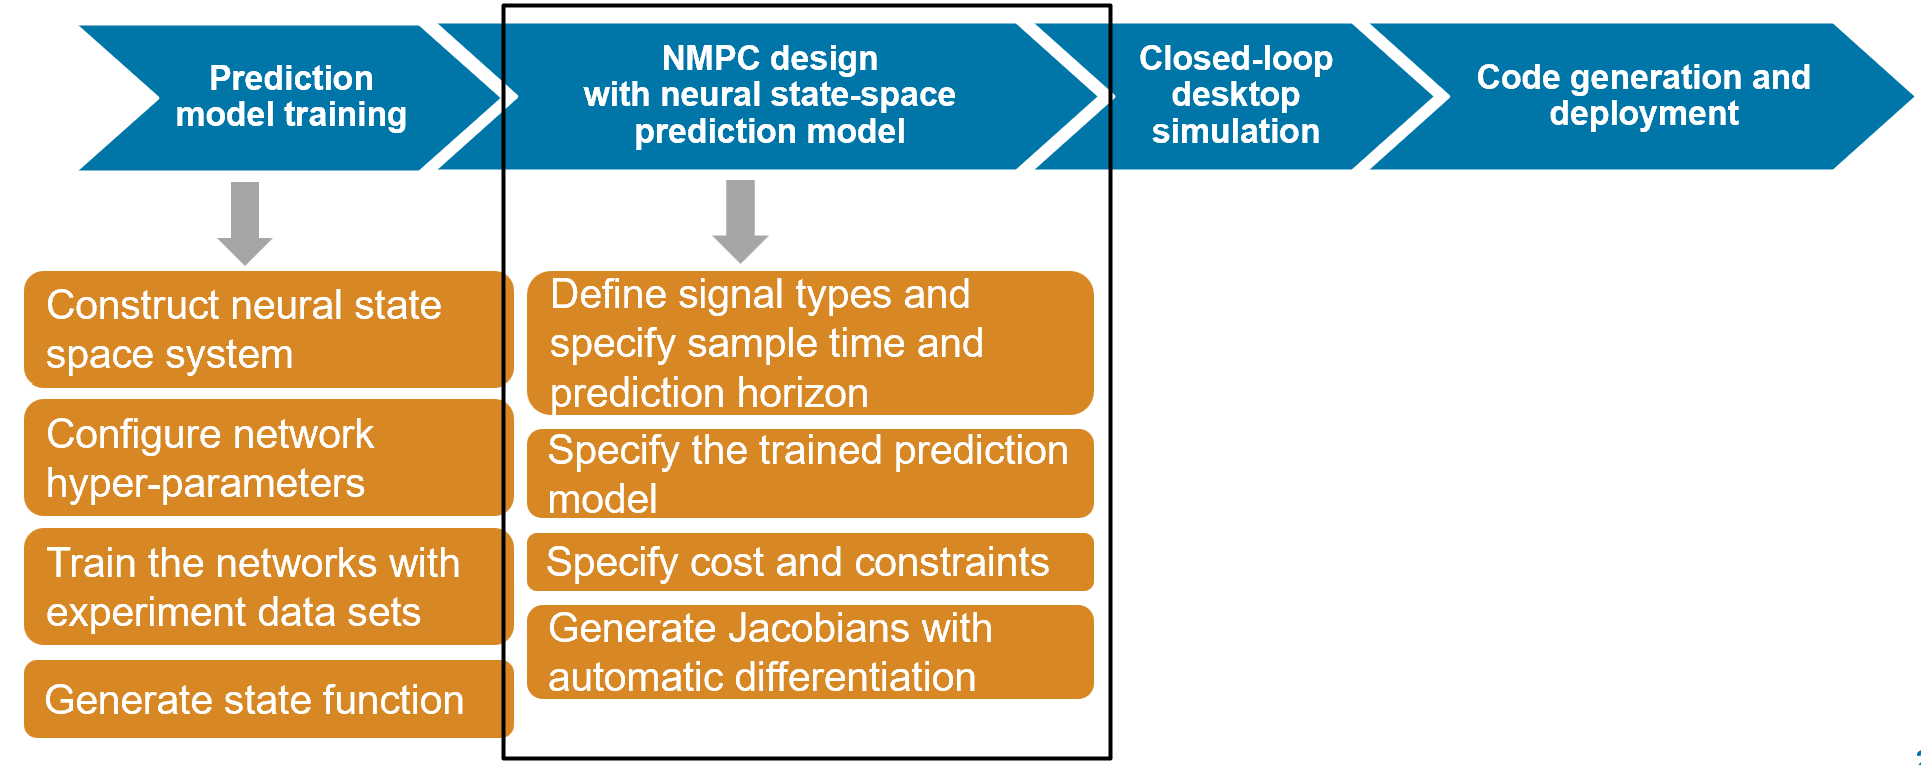

Compared with the generic nonlinear MPC controller ([`nlmpc` object](https://www.mathworks.com/help/mpc/ref/nlmpc.html)), [multistage nonlinear MPC](https://www.mathworks.com/help/mpc/ref/nlmpcmultistage.html) provides you with a more flexible and efficient way to implement MPC with staged costs and constraints. So we will be using multistage NLMPC in this example.

% Sample time in seconds
Ts = 60*5;
% Prediction horizon contains 48 steps (4 hours)
p = (4*3600)/Ts;

Please use the sample code below as reference and create an multistage NLMPC object. Refer to the documentation [here](https://www.mathworks.com/help/mpc/ref/nlmpcmultistage.html).

`nlobj = nlmpcMultistage(PredictionHorizon,NumberOfStates,'MV',mvIndex,'MD',mdIndex);`

`Note that in the model, heater input index is 2 and outdoor temeprature index is 1.`

nlobj = nlmpcMultistage(p,1,'MV',2,'MD',1);

% Sample time is 300 seconds
nlobj.Ts = Ts;
% MVRate is enabled and used in cost fucntion to penalize aggressive
% control action
nlobj.UseMVRate = true;
% Specify state name (house temperature)
nlobj.States.Name = 'Troom';
% Specify MV name (heater input) with a range between 0 and 1
nlobj.MV.Name = 'Pheat';
% Specify MD name (outdoor temperature)
nlobj.MD.Name = 'Tatm';

#### Specify the neural state-space prediction model in the controller object

% Specify the state function generated from the neural state-space model
nlobj.Model.StateFcn = "stateFcn";
% Specify the state fucntion is in discrete time
nlobj.Model.IsContinuousTime = false;

#### Specify stage cost and constraints

Stage cost and constraint functions, specified as an array of `p+1` structures (where `p` is the prediction horizon). Stage 1 corresponds to the current control interval and p+1 is the end of the prediction horizon. The overall cost function of the nonlinear MPC problem is the sum of the cost functions at each stage.

The cost function consists of 3 parts: electricity cost, slack variable for soft constraints (for the house temperature), and manipulated vairable move suppression. Open the file "myCostFcnwSlack.m" in the functions folder for details.

The constraint function is to maintain the house temeprature within the range of [$20\degree$C, $22\degree$C] with slack variables: $T_{\textrm{house}}^{\min } -{\textrm{Slack}}^{\min } \le T_{\textrm{house}} \le T_{\textrm{house}}^{\max } +{\textrm{Slack}}^{\max }$. The slack variables are always nonnegative. Open the file "myIneqConFunctionwSlack.m" in the functions folder for details.

% Specify cost function for the first stage
nlobj.Stages(1).CostFcn = 'myCostFcnwSlackStageFirst';
% Specify one paramter for the first stage (electricity price)
nlobj.Stages(1).ParameterLength = 1;
% Specify no slack variables for the first stage
nlobj.Stages(1).SlackVariableLength = 0;

% Specify cost Function for the last stage
nlobj.Stages(p+1).CostFcn = 'myCostFcnwSlackStageLast';
% Specify one parameter for the last stage (electricity price)
nlobj.Stages(p+1).ParameterLength = 1;
% Specify two slack variables for the last stage (upper and lower bound for house temperature)
nlobj.Stages(p+1).SlackVariableLength = 2;

% Specify cost function for the remaining stages with one parameter
% (electricity price) and two slack variables
for ct = 2:p
    nlobj.Stages(ct).CostFcn = 'myCostFcnwSlack';
    nlobj.Stages(ct).ParameterLength = 1;
    nlobj.Stages(ct).SlackVariableLength = 2;
end

% Specify inequality constraint function where two slack variables are used
% to make the upper and lower house temperature bounds implemented as soft
% constraints in MPC
for ct = 2:p+1
    nlobj.Stages(ct).IneqConFcn = 'myIneqConFunctionwSlack';
end

There is a limitation on the heat input which is specified as hard constraints on manipulated variable *Pheat*. It has to between 0 and 1. Specify the constraints for the manipulated variable *Pheat*. Use the following sample code and this [link](https://www.mathworks.com/help/mpc/ref/nlmpcmultistage.html#mw_2c5a79fb-fb34-40f1-b22a-4ca72a95c9e3) for reference:

`nlobj.MV.Min = -10;`

`nlobj.MV.Max = 10;`

% Specify bounds for the manipulated variable
nlobj.MV.Min = 0;   % Minimum
nlobj.MV.Max = 1;   % Maximum

#### Generate Jacobians with automatic differentiation

% Auto-generate Jacobian functions for the state, cost, and inequality
% constraints.
nlobj = nlobj.generateJacobianFunction("state");
nlobj = nlobj.generateJacobianFunction("cost");
nlobj = nlobj.generateJacobianFunction("ineqcon");

#### Validate functions

We will use [validateFcns](https://www.mathworks.com/help/mpc/ref/nlmpc.validatefcns.html) to examine prediction model and custom functions of nlmpcMultistage object for potential problems.

x0 = 20;
u0 = 0;
simdata.MeasuredDisturbance = 8;
simdata.StageParameter = ones(p+1,1);
validateFcns(nlobj,x0,u0,simdata);

Model.StateFcn is OK.
Model.StateJacFcn is OK.
"CostFcn" of the following stages [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49] are OK.
"CostJacFcn" of the following stages [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49] are OK.
"IneqConFcn" of the following stages [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49] are OK.
"IneqConJacFcn" of the following stages [2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49] are OK.
Analysis of user-provided model, cost, and constraint functions complete.


## Evaluate MPC Control Performance in Simulink

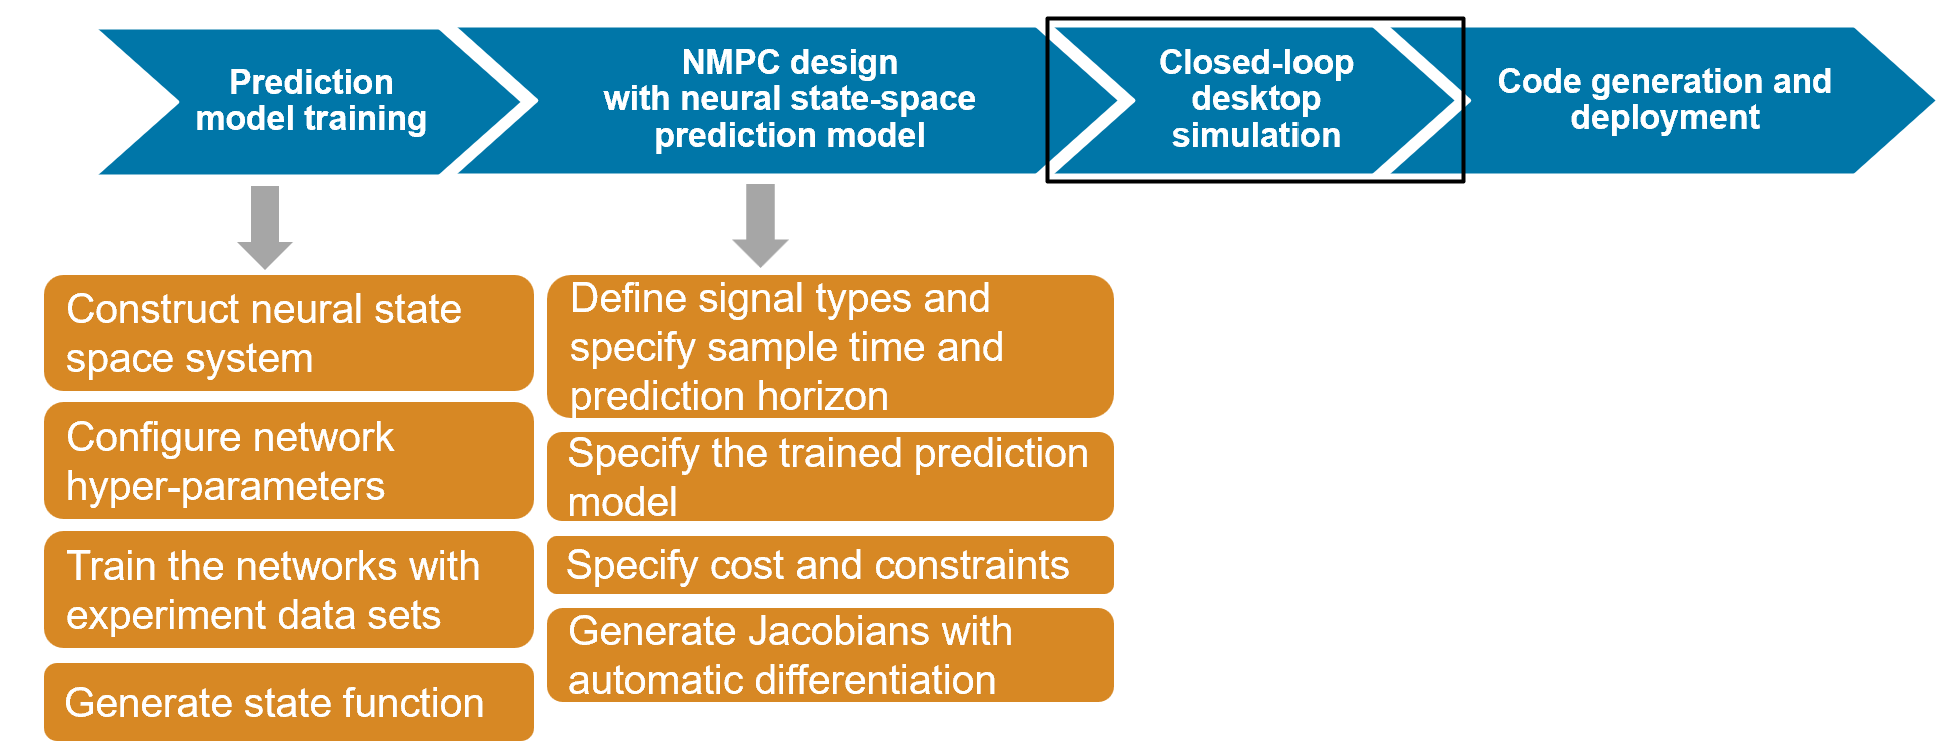

Now we can run simulation with the designed multistage nonlinear MPC in the Simulink model.

% Generate price and outdoor temperature forecast data for MPC simulation
[Tatm_w_for_preview,tou_pricing_for_preview,...
    TinIC,sinePhase,sineAmplitude,sineBias,sineFreq,...
    T_comfort_min,T_comfort_max] = forecastData(Ts);

Use the sim command to run the Simulink model for 86400 seconds (24 hours). Use the following sample code and this [link](https://www.mathworks.com/help/simulink/slref/sim.html#responsive_offcanvas) for reference:

simout = sim('simulink_model_name',"StopTime","3600");

% Simulate model for 24 hours
simout = sim('house_heating_system',"StopTime","86400");

% View pre-saved simulation results in Simulink Data Inspector
open("./SDI_session_with_presaved_simresults.mldatx");

The response shows that before the electricty price jumps at 10am (3.60e+4 in the plot below), MPC starts heating house up close to the upper bound to save energy cost.

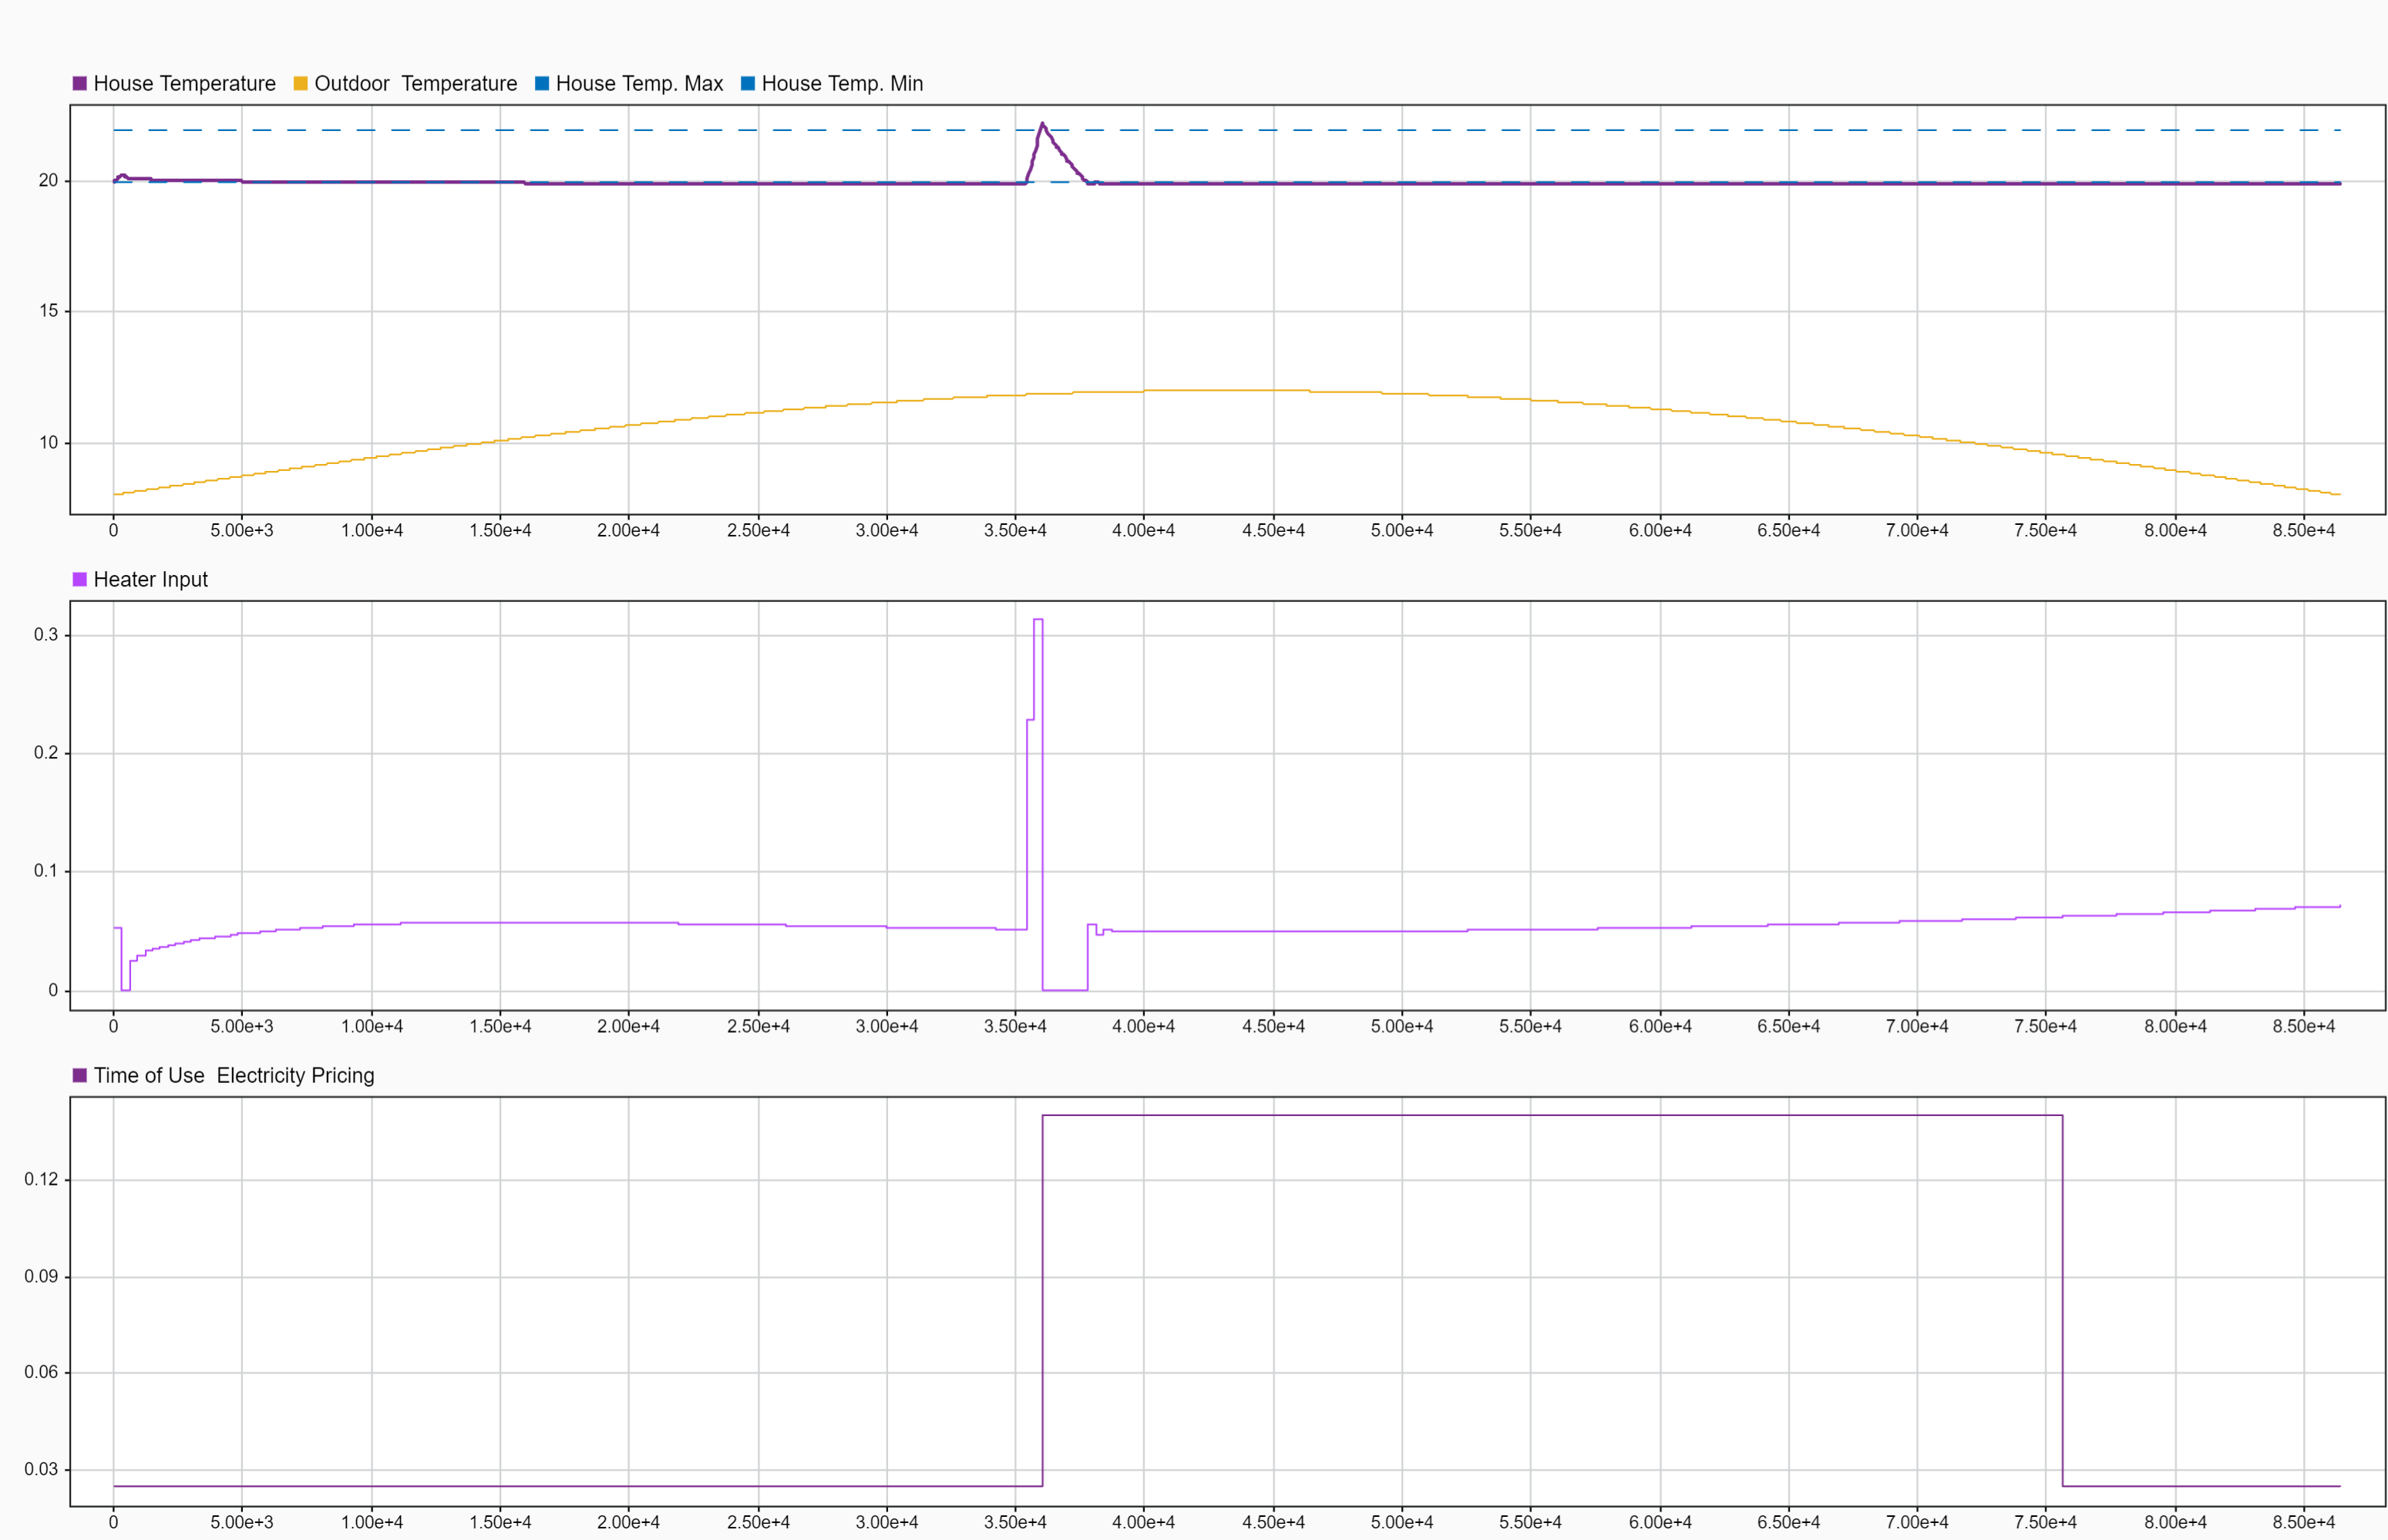

## Code Generation and Deployment

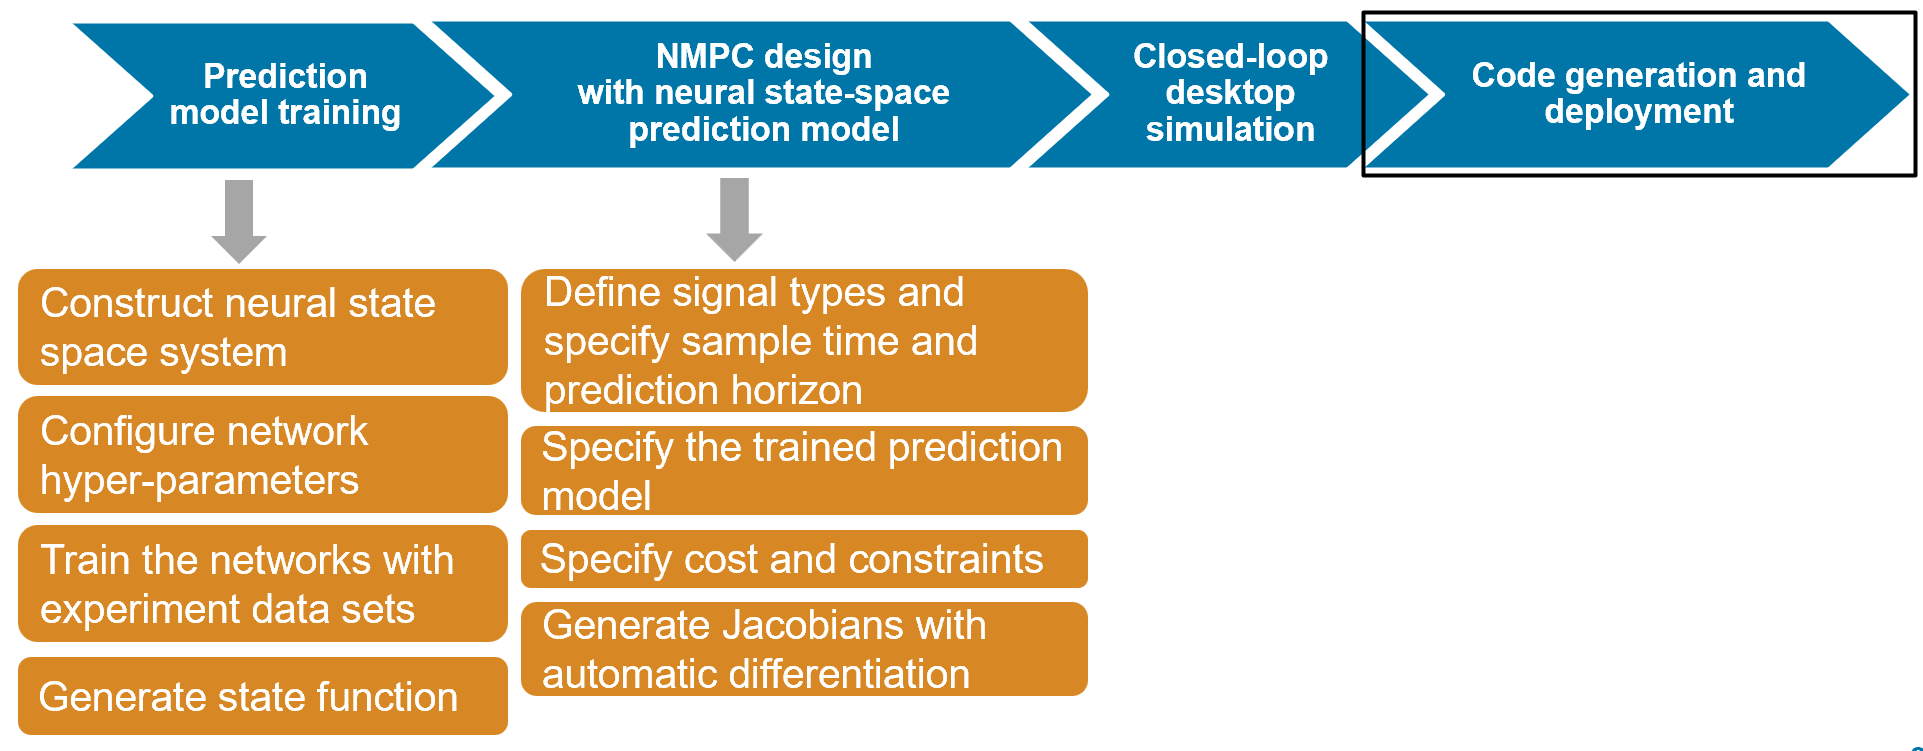

Once you are satisified with the performance of the controller, the last step is to generate code and deploy the designed controller. Please see this [link](https://www.mathworks.com/help/mpc/ug/generate-code-and-deploy-controller-to-real-time-targets.html) for details.